function estimate = directpi(Ntrials)
Nhits = 0;
for i = 1:Ntrials
    x = 2*rand()-1; %shifting uniformily distributed r.v from interval (0,1) to (-1,1)
    y = 2*rand()-1;
    if x^2 + y^2 <= 1
        Nhits = Nhits + 1;
    end
end
estimate=Nhits/Ntrials;%Nhits/Ntrials approx pi/4 
end

%from results below we can see that indeed the output of direct pi
%approaches pi/4 = 0.7854 to 4 d.p.

directpi(1000)

ans = 0.7880

directpi(10000)

ans = 0.7847

directpi(100000)

ans = 0.7849

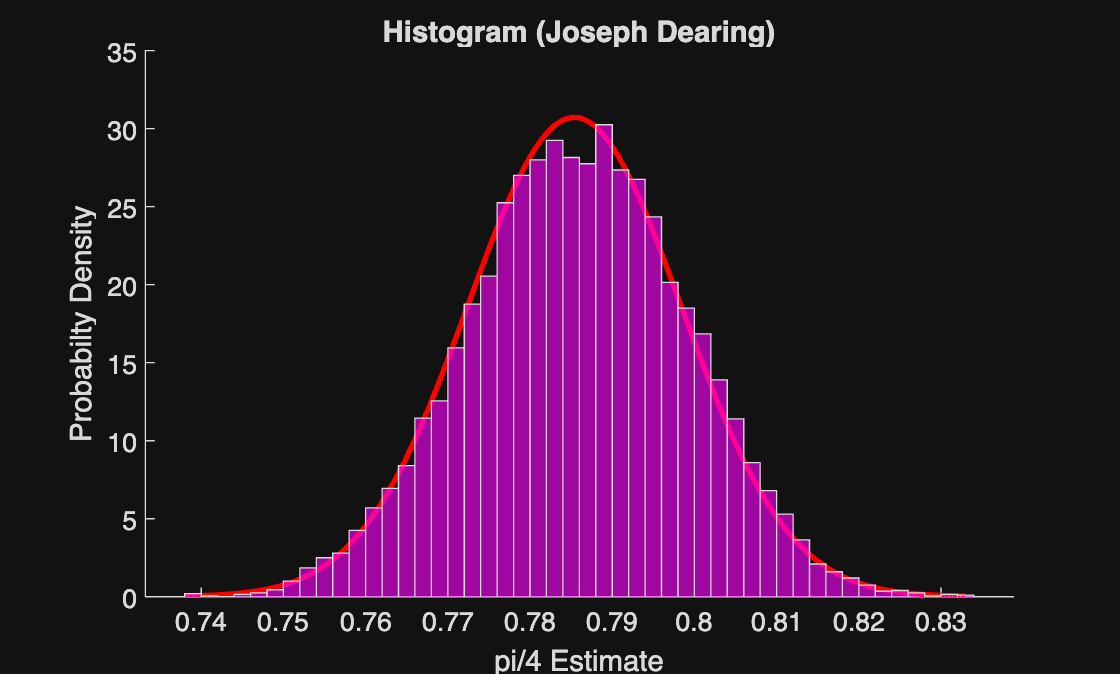

N = 1000;
runs = 10000;

estimates = zeros([1 runs]);
for i = 1:runs
    estimates(i) = directpi(N);
end

%Creating normal distribution with mean = pi/4 and var = theta(1-theta)/N
%such that theta = pi/4.
x=linspace(max(estimates),min(estimates),100);
y=pdf("normal",x,pi/4,sqrt((pi/4)*(1-pi/4)/1000));

hold on
plot(x,y,"red",linewidth=2)
histogram(estimates,'Normalization','pdf','FaceColor','m')
%Modifying from frequency to probabilty density on y-axis for comparison
%with normal distribution.

xlabel("pi/4 Estimate")
ylabel("Probabilty Density")
title("Histogram (Joseph Dearing)")


%From plot we can see that output is characterized by the normal
%distribution given above.
%This is expected, as by the central limit theorem, since the output is the
%average of N independant Bernoulli trials with p(hit)=pi/4.

function [cutoffs,indicies]=walker(K)
p=rand([1,K]);
p=p./sum(p); %normalizing so probabilities sum to 1
pmean=1/K; %avg of K probabilities that sum to 1 is always 1/K

tall=[]; %tall bucket
small=[]; %small bucket
cutoffs = []; %used for storing 
indicies = []; %used for storing index above cutoff (row 1) and index below cutoff (row 2)
j=1; %while loop variable

%sorting initial probabilities into buckets
for i = 1:K 
    if p(i) >= pmean
        tall = [tall,i];
    else
        small = [small,i];
    end
end

while ~isempty(small) && ~isempty(tall)
%taking the first small and tall bucket elements
    s=small(1);
    small(1) = [];
    t=tall(1);
    tall(1)=[];
%defning table cutoffs and indicies
    cutoffs = [cutoffs, p(s)];
    indicies(1,j)=t;
    indicies(2,j)=s;
    j=j+1;

    r=p(s)+p(t)-1/K; %the 'size' of the remainder
    p(t)=r; %replacing the original pk with the remainder for acsess later

%sorting the remainder into the corresponding bucket
    if r >= pmean 
        tall = [tall, t];
    else
        small = [small, t];
    end
end

%the remaining items in the buckets must have a 'size' of 1/K hence they fill their own column of the table
%for ease in later coding I have filled both sections of column in indicies matrix

while ~isempty(small)
    s = small(1);
    cutoffs = [cutoffs, pmean];
    indicies(1,j)=s;
    indicies(2,j)=s;
    j=j+1;
    small(1)=[];
end

while ~isempty(tall)
    t = tall(1);
    cutoffs = [cutoffs, pmean];
    indicies(1,j) = t;
    indicies(2,j) = t;
    j = j + 1;
    tall(1) = [];
end
end

%The reason we start with small is to keep the the code 0(1), as when we
%start with a small then a large stick we are only required to do one
%calculation in the sampling stage, simply is our 'stone' above or below
%the cutoffs. If we were to start with a tall stick we would eventually be
%left with all small sticks leading to 3 or more event probabilities in one
%column of the table. This would require more computation as we would have
%to determine which section the stone lands in, not just wether or not it
%lands above or below a cutoff.

[a,b]=walker(10)

a =     0.0401    0.0433    0.0420    0.0746    0.0649    0.0554    0.0730    0.0744    0.0950    0.1000


b =      1     3     6     7    10     1     3     7     7     7
     2     4     5     8     9     6    10     1     3     7



%Function takes our 'table' from walker function and outputs the number k
%of which element with probability pk is taken

function [k]=walker2(cutoffs,indicies) 
K=length(cutoffs);
i=randi([1 K]); %choosing column of 'table'
j=rand()/10; %chosing at what height 'stone' is thrown
if j > cutoffs(i) 
    k = indicies(1,i);
else
    k = indicies(2,i);
end
end

%The sampling stage is 0(1) since, regardless of K, we perform a fixed
%number of operations. The use of the random variables eliminates any
%searching through vectors and then we perform one caluculation, wether or
%not we lie above or below the cutoff.

walker2(a,b)

ans = 8